**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Autors: P.Ozga & P.Pramod 

dateset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

dateset from: by `Mustanger from kaggle link:`

https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input

### Toolbox: Statistics and Machine Learning & Deep Learning

## Get the path to the dataset and show first 5 sample.

close all;
% Get the path to the dataset and show first 5 samples
fpath = fullfile(pwd,'wine_quality_dataset.csv');                         % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
firstFive = head(fname, 5);                                       % Display first 5 rows
verticalView = array2table(firstFive.Variables', ...
    'VariableNames', strcat("Sample", string(1:5)), ...
    'RowNames', fname.Properties.VariableNames);
disp(verticalView);

                            Sample1    Sample2    Sample3    Sample4    Sample5
                            _______    _______    _______    _______    _______

    fixed acidity              7.4        7.8        7.8       11.2        7.4 
    volatile acidity           0.7       0.88       0.76       0.28        0.7 
    citric acid                  0          0       0.04       0.56          0 
    residual sugar             1.9        2.6        2.3        1.9        1.9 
    chlorides                0.076      0.098      0.092      0.075      0.076 
    free sulfur dioxide         11         25         15         17         11 
    total sulfur dioxide        34         67         54         60   

nonNumericCols = varfun(@isnumeric, fname);     % Check each columns
nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
if ~isempty(nonNumericColsNames)                %is numeric or no-numeric?
    disp('Database is non-numeric.');
    disp(nonNumericColsNames);
else
    disp('Each columns is numeric.');
    numRows = height(fname);  % lub: size(fname, 1);
    disp(['Number of rows: ', num2str(numRows)]);
end

Each columns is numeric.


Number of rows: 5605


% Numeric summary
numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
numericData = fname(:, numericCols);
minVals = varfun(@min, numericData, 'OutputFormat', 'uniform');
maxVals = varfun(@max, numericData, 'OutputFormat', 'uniform');
summaryVertical = table(minVals', maxVals', 'VariableNames', {'Min', 'Max'},'RowNames', numericData.Properties.VariableNames);
disp(summaryVertical);

                              Min       Max  
                            _______    ______

    fixed acidity               3.9      15.9
    volatile acidity           0.08      1.58
    citric acid                   0         1
    residual sugar              0.7     19.25
    chlorides                 0.012     0.611
    free sulfur dioxide           1       289
    total sulfur dioxide          6       440
    density                 0.98711    1.0037
    pH                         2.74      4.01
    sulphates                  0.22         2
    alcohol                       8      14.9
    quality                       3         9



Class Distribution

qualityCounts = countcats(categorical(fname.quality));
uniqueClasses = unique(fname.quality);
for i = 1:length(uniqueClasses)
    fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));
end

Class 3 has 330 samples
Class 4 has 1080 samples
Class 5 has 681 samples
Class 6 has 638 samples
Class 7 has 1079 samples
Class 8 has 1737 samples
Class 9 has 60 samples


## Normalization all data

X = fname{:, 1:11};                  % Features (first 11 columns)
Y = fname{:, 12};                    % Quality rating (12th column)
X = normalize(X, 'range');           % Min-Max normalization

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## Konwersja etykiet do formatu klasyfikacyjnego (one-hot)

Y_categorical = categorical(Y);
Y_dummy = dummyvar(Y_categorical);  % One-hot encoding

## Split the Data into Training and Test Sets:

### about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

%cv = cvpartition(Y_categorical, 'KFold', 5, 'Stratify', true); % K-Fold cross-validation
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv, 1), :);             % For the first fold
Y_train = Y_dummy(training(cv, 1), :);       % For the first fold
X_test = X(test(cv, 1), :);                  % For the first fold
Y_test = Y_dummy(test(cv, 1), :);

Compute weight for class

classCounts = countcats(categorical(Y));
totalSamples = sum(classCounts);
classWeights = totalSamples ./ classCounts;

## Create and Train the MLP (Multilayer Perceptron) Network:

### about `feedforwardnet `function, link: https://ch.mathworks.com/help/deeplearning/ref/feedforwardnet.html

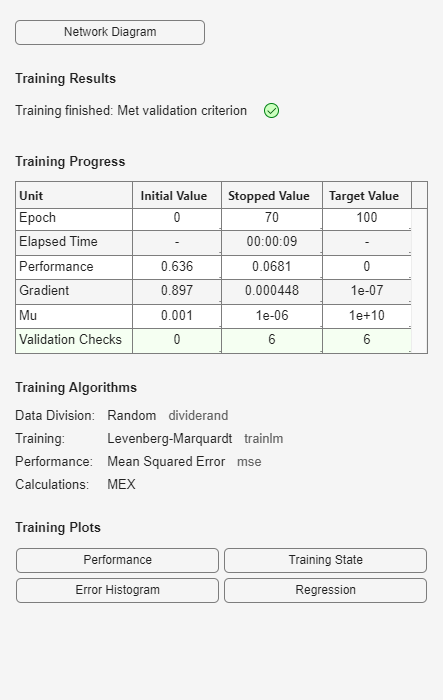

hiddenLayerSize = 12;
net = feedforwardnet(hiddenLayerSize);       % MLP for classification
net.performFcn = 'crossentropy';             % Loss function for classification
net.trainFcn = 'trainlm';                    % Levenberg-Marquardt
net.trainParam.epochs = 100;
net.trainParam.show = 50;
%net.performParam.normalization = 'none';     %!
%net.trainParam.showWindow = false;  % Wyłączenie okna GUI podczas treningu

%net.performParam.classWeights = classWeights;  % Ustawienie wag dla klas

% Trening
[net, tr] = train(net, X_train', Y_train');

## Test the Network

Y_pred = net(X_test');           % Predict (column)
Y_pred_class = vec2ind(Y_pred);  % From prediction to labels
Y_true_class = vec2ind(Y_test'); % From labels to index

Calculate Precision, Recall, F1-score

confMat = confusionmat(Y_true_class, Y_pred_class);
numClasses = size(confMat, 1);
precision = zeros(numClasses,1);
recall = zeros(numClasses,1);
f1 = zeros(numClasses,1);

for i = 1:numClasses
    TP = confMat(i,i);
    FP = sum(confMat(:,i)) - TP;
    FN = sum(confMat(i,:)) - TP;
    precision(i) = TP / (TP + FP + eps);
    recall(i) = TP / (TP + FN + eps);
    f1(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i) + eps);
end

disp('Class | Precision | Recall | F1-score');

Class | Precision | Recall | F1-score


for i = 1:numClasses
    fprintf('  %2d   |   %.2f    | %.2f   |  %.2f\n', i, precision(i), recall(i), f1(i));
end

   1   |   0.93    | 0.36   |  0.52
   2   |   0.63    | 0.79   |  0.70
   3   |   0.56    | 0.73   |  0.64
   4   |   0.42    | 0.46   |  0.44
   5   |   0.64    | 0.14   |  0.22
   6   |   0.66    | 0.89   |  0.76
   7   |   0.00    | 0.00   |  0.00


macroPrecision = mean(precision);
macroRecall = mean(recall);
macroF1 = mean(f1);

fprintf('\nMacro-avg Precision: %.2f\n', macroPrecision);


Macro-avg Precision: 0.55


fprintf('Macro-avg Recall: %.2f\n', macroRecall);

Macro-avg Recall: 0.48


fprintf('Macro-avg F1-score: %.2f\n', macroF1);

Macro-avg F1-score: 0.47


## Ocena jakości klasyfikacji

accuracy = sum(Y_pred_class == Y_true_class) / length(Y_true_class);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 61.11%


## Confusion Matrix

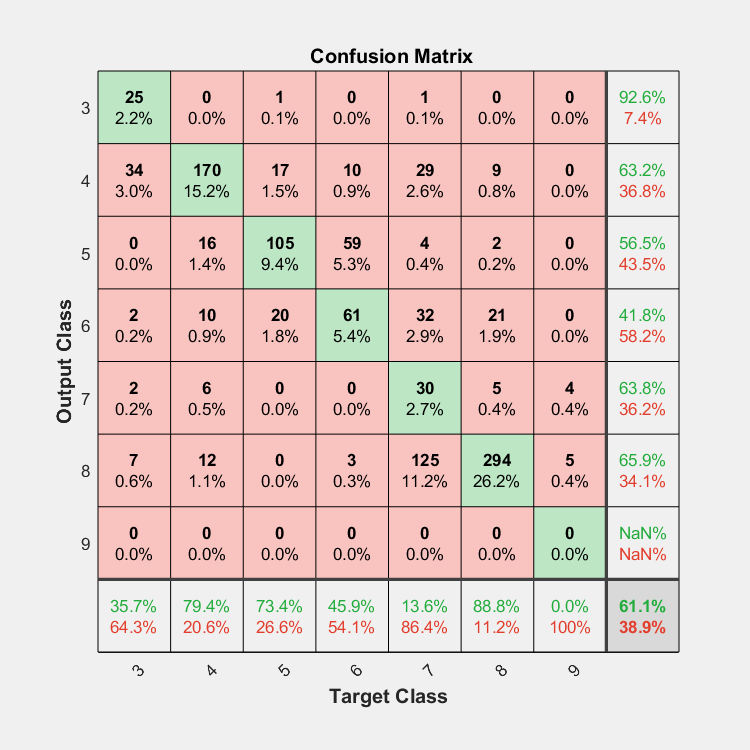

figure;
plotconfusion(Y_test', Y_pred);
classLabels = {'3','4','5','6','7','8','9',' '};

% Zmień etykiety osi
ax = gca;
ax.XTickLabel = classLabels;
ax.YTickLabel = classLabels;

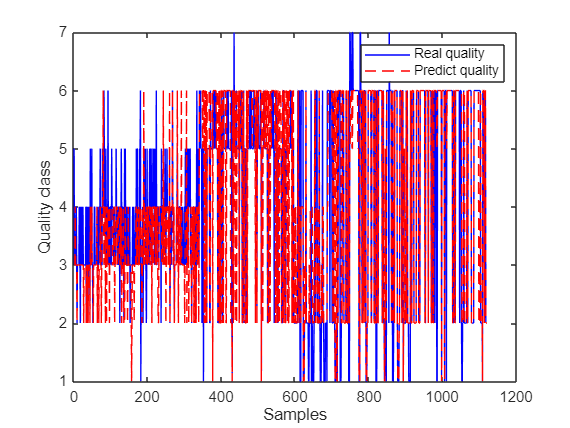

% Porównanie rzeczywistych i przewidywanych klas
figure;
plot(Y_true_class, 'b'); hold on;
plot(Y_pred_class, 'r--');
legend('Real quality', 'Predict quality');
xlabel('Samples');
ylabel('Quality class');